# M1 AHU Vibration Analysis

This script uses the AHU vibration power spectrum density (PSD) $U_\text{seg}(j\omega)$ and the telescope frequency response $H(j\omega)$ to perform a set of analysis regarding the impact of the vibration load into the image quality.

Preamble

- Clear workspace

- Radians to mas ($10^{-3}$ arc seconds) conversion constant

- Define root sum of squares (RSS) function

clearvars
rad2mas = (180/pi * 3600 * 1000);   % Radians to mili arc second conversion constant
rss = @(x,dir)sqrt(sum(x.^2,dir));  % Root of the sum of squared values function

## Load AHU vibration PSD

load("ahu_psd_1KHz_1400rpm.mat","psdAHUf","freq");

`psdAHUf` provides the vibration power spectrum density (PSD) data $U_\text{seg}(j\omega)$ as an $n_f \times 6$ matrix, where $n_f$ is the number of frequency samples. The frequencies in (Hz) are available from `freq.` The columns are the forces ($F_x$, $F_y$, and $F_z$) and moments ($M_x$, $M_y$, and $M_z$), expressed in $\text{N}^2/\text{Hz}$ and $\text{N}^2\text{m}^2/\text{Hz}$, respectively.

## Calculate the M1 AHU transfer function

Choose the wavefront control mode corresponding to the rejection transfer function to be applied to the frequency response model outputs:

WFC_MODE = "LTAO"

WFC_MODE = "LTAO"

Checking for available FR files for model 20251110_1617...
Loading modal model parameters from 
/home/rromano/mnt/20251110_1617_zen_30_M1_202110_FSM_202305_Mount_202305_pier_202411_M1Fans/modal_state_space_model_2ndOrder.mat
The model maximum eigenfrequency is 299.89069Hz

TT sensitivity matrix loaded from 
lom_tt_dt.mat
Piston sensitivity matrix loaded from 
D_seg_piston_dt.mat
Calculating FR model at the AHU PSD frequency points.
Computing frequency response from 0-500Hz
S1 done!
S2 done!
S3 done!
S4 done!
S5 done!
S6 done!
S7 done!
AHU FR computation complete!
TF frequency response data saved as G_20251110_1617zeta2pct_ahu_fr_var_3.mat


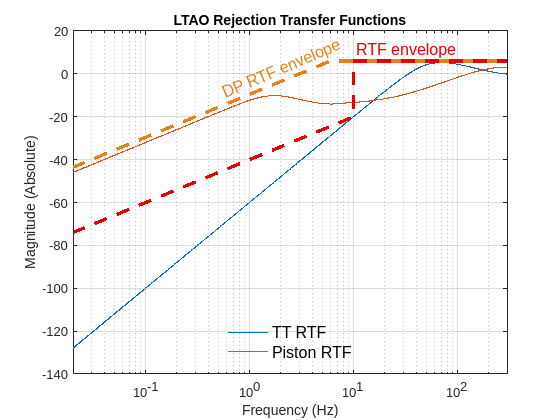

plot_wfc_rtf = false;
run('calc_m1ahu_fr.mlx');

## General analysis

Let $H_\text{ttp}(\j\omega)$the frequency response matrix represent the GMT structural dynamics whose inputs are the forces and moments applied to nodes at the M1 fan locations and the outputs are the segment tip-tilt (TT) and the piston at the exit pupil. Refer to script `calc_m1ahu_fr.mlx` for details.

In the following, we compute the TT and piston PSD ($$\text{mas}^2/\text{Hz}$$ and $$\text{nm}^2/\text{Hz}$$, respectively) using 


$$Y_\text{TTP}(j\omega) = \left|H_\text{ttp}(j\omega) \right|^2
\left(\mathbf{1}_{98} \otimes U_{\text{AHU}}(j\omega)\right)$$


The symbol $
\otimes$stands for the Kronecker product and $\mathbf{1}_{n_1}$ is an $n_1$-dimensional column vector filled with ones, such that

$\mathbf{1}_3 \otimes U_\text{AHU}(j\omega) = \left[
\begin{array}{c}
U_\text{AHU}(j\omega) \\ U_\text{AHU}(j\omega) \\ U_\text{AHU}(j\omega)
\end{array}
\right]$.

Therefore, $\mathbf{1}_{98} \otimes U_\text{AHU}(j\omega)$ means that the same force and moment vibration load $U_\text{seg}$ is applied in all the fan nodes. The power spectrum density $Y_\text{TTP}$ is 21-dimensional. According to the telescope frequency response model, the first 14 elements of $Y_\text{TTP}$ are the tip-tilt PSD and the last 7 provide the segment piston.

*In terms of implementation, the telescope frequency response representing the effect of the load applied on each M1 segment is available from a different data file (*`m1s``X``fanTF.mat`*) computed beforehand. For this reason, the code below performs two *`for`* loops: an outer one, which considers the frequency response model due to the excitation on each segment, and an inner iteration, to compute the tip-tilt and piston PSD of each segment. *

tt_psd = zeros(14,nw);
piston_psd = zeros(7,nw);

Uahu = kron(ones(1,14*7),psdAHUf);
% PTT computation loop: each iteration provides the Tip/tilt/piston PSD
% as a response of the forces (and moments) applied to the M1 AHU locations.
for k2 = 1:7
    tt_psd(k2,:) = sum(abs(squeeze(H_ttp.ResponseData(k2,:,:)))'.^2 .* Uahu,2);
    tt_psd(k2+7,:) = sum(abs(squeeze(H_ttp.ResponseData(k2+7,:,:)))'.^2 .* Uahu,2);
    piston_psd(k2,:) = sum(abs(squeeze(H_ttp.ResponseData(k2+14,:,:)))'.^2 .* Uahu,2);
end

### Cumulative TT and Piston Power Spectrum Densities

Below, we present the cumulative power spectrum (CPS). Each line represents the effect of the load applied on a particular M1 segment.

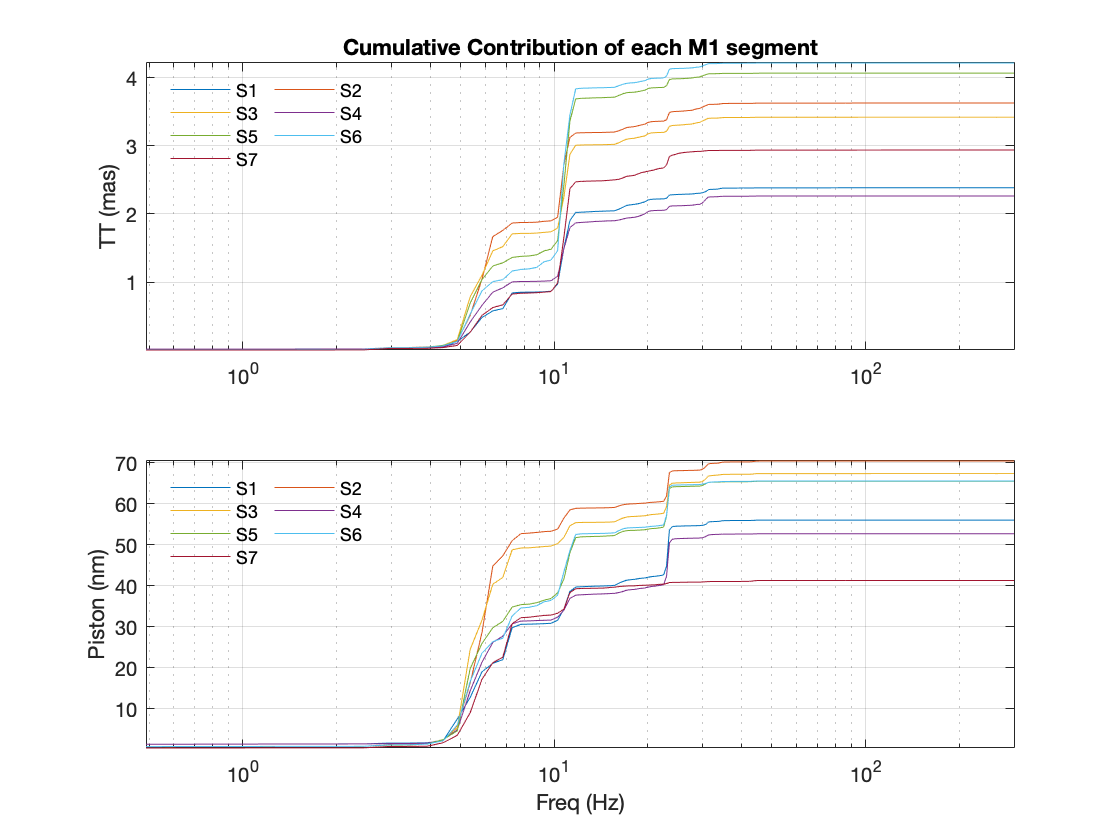

DeltaFs = diff(om(1:2)/2/pi);
w = om(2:n_om);

figure(200);
for i1 = 1:7    
    subplot(211);
    tt_cumPSD_mas = rad2mas*sqrt( DeltaFs*( cumsum(sum(tt_psd(1:7,i1,2:end),1).^2) +...
        cumsum(sqrt(sum(tt_psd(7:14,i1,2:end),1).^2)) ));
    
    semilogx(w/2/pi, squeeze(tt_cumPSD_mas)); hold on;
    subplot(212);
    semilogx(w/2/pi, squeeze(1e9*sqrt(DeltaFs*cumsum( sum(piston_psd(:,i1,2:end),1) )))); hold on;
end

subplot(211);
title('Cumulative Contribution of each M1 segment');
ylabel('TT (mas)');
grid on; hold off; axis tight;
legend('S1','S2','S3','S4','S5','S6','S7','Orientation','Horizontal',...
    'Location','northwest','NumColumns',2); legend boxoff;

subplot(212)
ylabel('Piston (nm)');
xlabel('Freq (Hz)');
grid on; hold off; axis tight;
legend('S1','S2','S3','S4','S5','S6','S7','Orientation','Horizontal',...
    'Location','northwest','NumColumns',2); legend boxoff;

### Overall PTT effect and WFE

Let the $Y_i(j \omega)$ the $i^\text{th}$ element of $Y_\text{TTP}(j\omega)$, we compute the overall TT (in mas) as


$$\phi = 
\sqrt{\frac{1}{7}\int_0^{\infty} \sum_{i=1}^{14} Y_i(j\omega) d\omega }.$$


Similarly, the overall differential piston (in meters) reads as


$$\rho = \sqrt{\frac{1}{7}\int_0^{\infty} \sum_{i=15}^{21} Y_i(j\omega) d\omega }.$$


As proposed in GMT-DOC-04861, the $1/7$ factor aims at taking the mean tip-tilt and differential piston over the contributions of all segments. Thus, the expression of the overall M1 AHU vibration effect on the wavefront error (WFE) in (in meters) is

$\text{WFE} = \sqrt{\frac{R^2}{4} \left(3.6\times 10^6\frac{\pi}{180}\phi\right)^2 + \rho^2}$,

where $R=8.4$m.

total_tt = rad2mas*sqrt( DeltaFs*sum(tt_psd(:,:,2:end), 'all') /7);
total_piston = 1e9*sqrt( DeltaFs*sum(piston_psd(:,:,2:end),'all') /7);

R = 8.4;    
total_wfe = sqrt(((total_tt/rad2mas)^2 * R^2/4)*1e18 + total_piston^2);
fprintf("Overall optical metrics:\nTT=%.3gmas \t Piston=%.3gnm \t WFE=%.3gnm \n",...
    total_tt, total_piston, total_wfe);

Overall optical metrics:
TT=4.2mas 	 Piston=60.6nm 	 wfe=105nm 


## Rejection transfer functions (RTFs)

Function to compute the NS RTF (according to REQ-L3-OAD-35337)

function [rtf,L] = oad_NS_rtf(w) %#ok<DEFNU> 

% PZT closed-loop bandwidth (Hz)
fz = 25;
% PZT control loop damping
delta = 0.6;
% TT loop sampling period
T = 5e-3;
% TT sensor delay
tau = 6e-3;
% TT "integral gain" - actually the considered integral gain is gi/T
gi = 0.3;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the GLAO RTF (according to REQ-L3-OAD-35398)

function [rtf,L] = oad_AOTT_rtf(w)

% LTAO RTF (according to REQ-L3-OAD-35398)
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.75;   % ASM control loop damping
T = 2e-3;   % TT loop sampling period
tau = 1e-3; % TT sensor delay
gi = 0.4;   % TT "integral gain"

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the differential piston RTF

function RTF_DP = getRTF_DP(om)
    
s = sqrt(-1)*om;

%% FROM DRD rev F
omz = 800*2*pi;
dz = .75;
Tp = 30;
taup= 6/1000;
gpi = .5;
Te = 2/1000;
taue = .1/1000;
geff = .8;

num = 1 + omz^2*geff*exp(-taue*s).*(exp(-Te*s)-1)./(Te*s.*    (omz^2+2*omz*dz*s+s.^2) );
den = 1 - omz^2*gpi*exp(-taup*s).*(exp(-Tp*s)-1)./(Tp^2*s.^2.*(omz^2+2*omz*dz*s+s.^2) );
RTF_DP = num./den;
    
end